LAB EXERCISE - 8

Sudarshan Rao

BL.AI.U4AID25064

% example 
x = [14,3,2,1];
p = [0.6,0.3,0.08,0.02];

mnpdf(x,p)

ans = 0.0063

% example 
% for discrete 
y = [3,4,1];
Mu = [2,5,-1];
v = [2,1,1;1,2,1;1,1,2];

mvncdf(y,Mu,v)

ans = 0.2223


% for continous - i think

xl = [-1,1,0];
xu = [3,4,1];

mvncdf(xl,xu,Mu,v)

ans = 0.0106

% example
P=[0.2,0.3,0.5];
X=mnrnd(500,P)

X =    105   145   250


% example 
P=[0.2,0.3,0.5];
X=mnrnd(500,P,10)

X =    103   141   256
   100   142   258
    91   154   255
    88   147   265
    95   137   268
    97   148   255
    99   171   230
   107   157   236
   106   151   243
   100   150   250


% exmaple
Mu = [2,10,30;5,3,15;3,4,8];
v = [8,5,4];
M = Mu'*Mu;

D = mvnrnd(v,M,10)

D =     3.9141   -1.9332  -23.3407
    3.1658    5.3812    0.9927
    6.7788   15.5637   21.7484
    0.0666    2.2918  -10.8176
   19.6405   20.5079   46.4552
   11.1060   13.1800   27.0566
    3.3005   -0.6227  -20.7746
    7.9569    1.2809   -5.1757
   13.9208    6.9386   20.1980
    6.9288   -2.7456  -28.0632


% example
A = rand(3)

A =     0.6939    0.6348    0.9353
    0.2949    0.3989    0.4489
    0.5707    0.2489    0.5318


[Q,R] = qr(A)

Q =    -0.7338   -0.3322   -0.5926
   -0.3118   -0.6102    0.7283
   -0.6036    0.7192    0.3442


R =    -0.9456   -0.7404   -1.1473
         0   -0.2753   -0.2022
         0         0   -0.0443


D = diag([1,2,3]);
V = Q*D*Q'

V =     1.8127   -0.6604   -0.6468
   -0.6604    2.4332    0.0624
   -0.6468    0.0624    1.7542


eigenvalues = eig(V)

eigenvalues =     3.0000
    1.0000
    2.0000


% example
A = rand(2)

A =     0.4232    0.2847
    0.9148    0.5750


[Q,R] = qr(A)

Q =    -0.4199   -0.9076
   -0.9076    0.4199


R =    -1.0080   -0.6413
         0   -0.0169


D = diag([1,2]);
V = Q*D*Q'

V =     1.8237   -0.3811
   -0.3811    1.1763


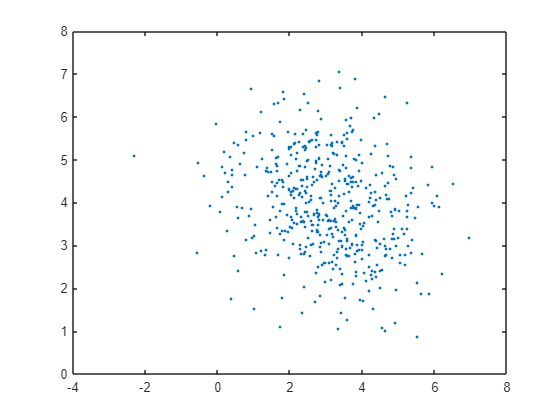

mu = [3,4];

r = mvnrnd(mu , V , 500);
plot(r(:,1),r(:,2),'.');

axis;

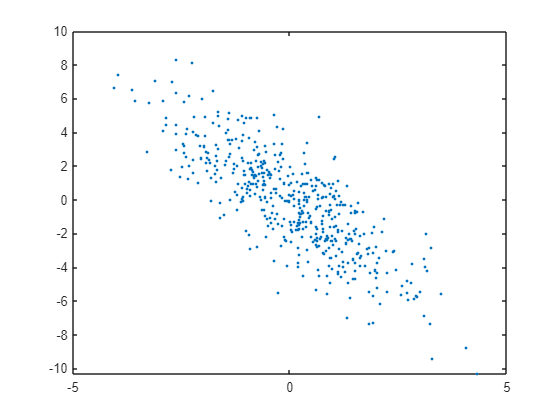

% example
clc;
clear all;

varx = 2;
vary = 9;

corcoeff = -0.8;
covxy = corcoeff*sqrt(varx*vary);

V = [varx covxy ; covxy vary];
mu = [0,0];
r = mvnrnd(mu,V,500);
plot(r(:,1),r(:,2),'.')

LAB Practise Questions

% question - 1
% 1. Four electronic ovens that were dropped during shipment are inspected and classified as containing
% either a major, a minor, or no defect. In the past, 35% of dropped ovens had a major defect, 25% had
% a minor defect, and 40% had no defect. Assume that the defects on the four ovens occur independently.

x = [0.35,0.25,0.40];

%a
p1 = (0.35)^4

p1 = 0.0150

%b
p2 = factorial(4)/(factorial(2)*factorial(1)*factorial(1)) *(0.40)^2 * 0.35 * 0.25

p2 = 0.1680

%c
p3 = factorial(4)/(factorial(2)*factorial(2)) * (0.25)^2 * (0.35)^2

p3 = 0.0459

%d
p4 = (0.40)^4

p4 = 0.0256

% question - 2
% 2. In the transmission of digital information, the probability that a bit has high, moderate, or low
% distortion is 0.03, 0.17, and 0.8, respectively. Suppose that three bits are transmitted and that the
% amount of distortion of each bit is assumed to be independent.
% (a) What is the probability that two bits have high distortion and one has moderate distortion?
% (b) What is the probability that all three bits have low distortion?
% (c) What is the probability that all three bits have moderate distortion?
% (d) What is the probability that all three bits have high distortion?
% (e) If X and Y denote the number of bits with high and moderate distortion, find the mean and variance
% of X and Y.

p = [0.03,0.17,0.8];
%a
p1 = factorial(3)/(factorial(2)*factorial(1)) * (0.03)^2 * 0.17

p1 = 4.5900e-04

%b
p2 = (0.8)^3

p2 = 0.5120

%c
p3 = (0.17)^3

p3 = 0.0049

%d
p4 = (0.03)^3

p4 = 2.7000e-05

%e
meanx = 3 * 0.03

meanx = 0.0900

varx = 3 * 0.03 * (1 - 0.03)

varx = 0.0873


meany = 3*0.17

meany = 0.5100

vary = 3*0.17*(1-0.17)

vary = 0.4233

% question - 3
% If X, Y and Z are normal random variables with mean 3, -4 and 2,
% respectively, generate a covariance matrix from a random matrix and
% evaluate the following:
% (a) P(X<3, Y<1, Z<2)
% (b) P(0<X<3, -1<Y<1, -2<Z<1)
% (c) P(-1<X<3, 1<Y<4, 0<Z<1)
% (d) P(X<1, Y<2, Z<1)

clear all
clc

A = rand(3);

[Q,R] = qr(A);

D = diag([1 2 3]);

V = Q*D*Q';

mu = [3 -4 2];

% a
X = [3 1 2];
p1 = mvncdf(X,mu,V)

p1 = 0.1952


% b
XL = [0 -1 -2];
XU = [3 1 1];
p2 = mvncdf(XL,XU,mu,V)

p2 = 0.0017


% c
XL = [-1 1 0];
XU = [3 4 1];
p3 = mvncdf(XL,XU,mu,V)

p3 = 1.9552e-05


% d
X = [1 2 1];
p4 = mvncdf(X,mu,V)

p4 = 0.0073

% question - 4
% Generate a sample of size 1000 from a multivariate normal population

clear all
clc

mu = [15 21 -18];

V = [10 1 1;
     1 10 1;
     1 1 10];

Data = mvnrnd(mu,V,1000);

size(Data)

ans =         1000           3



sample_mean = mean(Data)

sample_mean =    14.8937   21.1460  -18.0185



sample_covariance = cov(Data)

sample_covariance =     9.9813    1.0662    0.3093
    1.0662   11.4165    1.1734
    0.3093    1.1734    9.5387


% question - 5

clear all
clc

% a

P = [0.3 0.6 0.1];

Y = mnrnd(50,P)

Y =     13    33     4



% b

Prob = mnpdf(Y,P)

Prob = 0.0178

% question - 6

clear all
clc

P = [0.1 0.3 0.4 0.1 0.1];

% a

Y = mnrnd(500,P)

Y =     61   150   195    51    43



% b

X = [48 129 199 56 68];

Prob = mnpdf(X,P)

Prob = 6.4885e-08


% c

R = mnrnd(500,P,100);

EVeryGood = mean(R(:,1))

EVeryGood = 50.6100


EGood = mean(R(:,2))

EGood = 150.5800


EAverage = mean(R(:,3))

EAverage = 199.5900


EBad = mean(R(:,4))

EBad = 49.3400


EVeryBad = mean(R(:,5))

EVeryBad = 49.8800

% question - 7

clear all
clc

A = rand(7);

[Q,R] = qr(A);

Q

Q =    -0.2505    0.4515   -0.3466    0.2010    0.4429   -0.4834   -0.3783
   -0.5990    0.0565    0.5907    0.0926   -0.3118   -0.4083    0.1287
   -0.2098   -0.0496   -0.0920    0.7078   -0.3105    0.4428   -0.3893
   -0.4799   -0.6645   -0.3838    0.0803    0.2818   -0.0440    0.3051
   -0.3698    0.0405   -0.3675   -0.6176   -0.4505    0.1064   -0.3617
   -0.0475    0.4689   -0.4334    0.1735   -0.3363    0.0144    0.6683
   -0.4064    0.3570    0.2287   -0.1789    0.4634    0.6245    0.1352



QQT = Q*Q'

QQT =     1.0000    0.0000         0    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    1.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
         0    0.0000    1.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000    1.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000    1.0000         0   -0.0000
   -0.0000    0.0000   -0.0000    0.0000         0    1.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    1.0000



QTQ = Q'*Q

QTQ =     1.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000         0   -0.0000   -0.0000    0.0000
    0.0000    0.0000    1.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0000         0   -0.0000    1.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000    1.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    1.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    1.0000


% question - 8

clear all
clc

A = rand(9);

[Q,R] = qr(A);

D = diag([1 2 3 4 5 6 7 8 9]);

S = Q*D*Q';

eigenvalues = eig(S)

eigenvalues =     1.0000
    2.0000
    9.0000
    3.0000
    4.0000
    8.0000
    5.0000
    7.0000
    6.0000



all(eigenvalues > 0)

ans = logical
   1


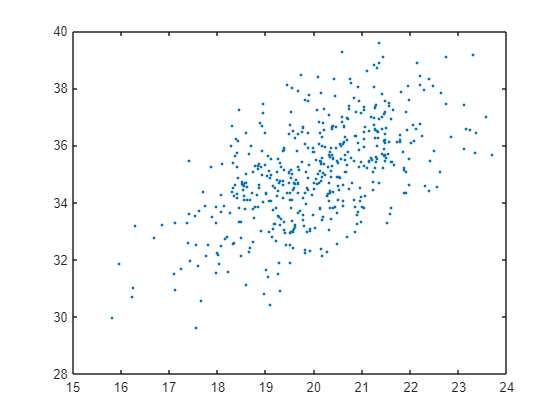

% question - 9

clear all
clc

varx = 2;

vary = 3;

corrcoefxy = 0.6;

covxy = corrcoefxy*sqrt(varx*vary);

V = [varx covxy;
     covxy vary];

mu = [20 35];

r = mvnrnd(mu,V,500);

plot(r(:,1),r(:,2),'.')


sample_mean = mean(r)

sample_mean =    20.0298   35.0481



sample_covariance = cov(r)

sample_covariance =     1.8460    1.3779
    1.3779    3.0653


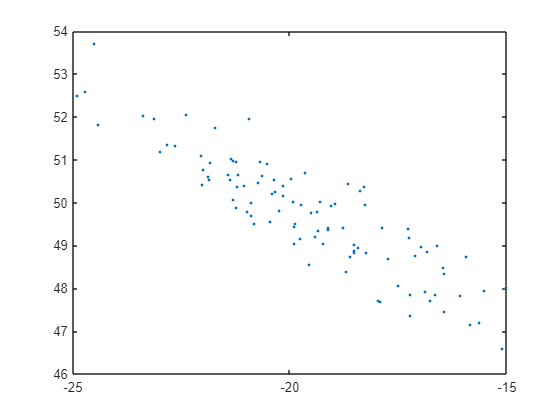

% question - 10

clear all
clc

varx = 5;

vary = 2;

corrcoefxy = -0.9;

covxy = corrcoefxy*sqrt(varx*vary);

V = [varx covxy;
     covxy vary];

mu = [-20 50];

r = mvnrnd(mu,V,100);

plot(r(:,1),r(:,2),'.')


sample_mean = mean(r)

sample_mean =   -19.5766   49.7420



sample_covariance = cov(r)

sample_covariance =     5.0660   -2.7100
   -2.7100    1.8097
